## Malaria Classification Evaluation

### Setting up test images directories

clc;clear all;close all; % for clean up

infected_dir = './test_images/infected/';
non_infected_dir = './test_images/NotInfected/';

### Testing on Normal Images

All of the images under the **NotInfected** directory are **Normal** Images

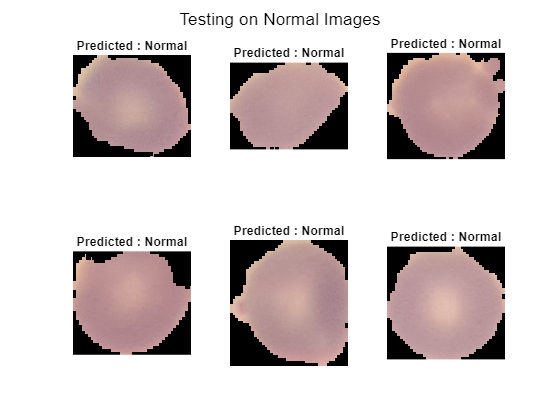

srcDir = non_infected_dir;
srcFiles = dir(fullfile(srcDir,'*.png'));
figure('Name','Normal');
for k = 1:6
    filename = fullfile(srcDir,srcFiles(k).name);
    I = imread(filename);
    pred = predict_malaria(I);
    if pred
        pred_label = 'Malaria';
    else
        pred_label = 'Normal';
    end
    subplot(2,3,k);imshow(I);title(['Predicted : ',pred_label]);
end
sgtitle('Testing on Normal Images')

### Testing on Malarial Images

All of the images under the **infected** directory are **Malaria** Images

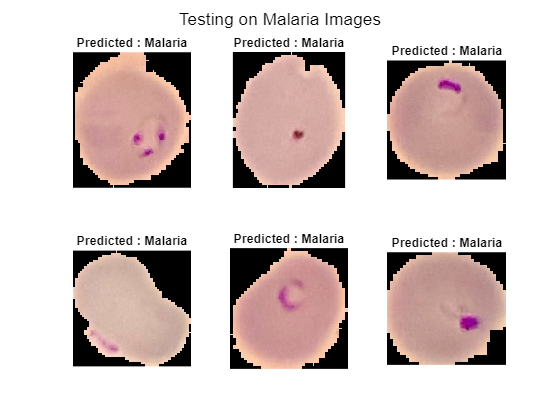

srcDir = infected_dir;
srcFiles = dir(fullfile(srcDir,'*.png'));
figure('Name','Malaria');
for k = 1:6
    filename = fullfile(srcDir,srcFiles(k).name);
    I = imread(filename);
    pred = predict_malaria(I);
    if pred
        pred_label = 'Malaria';
    else
        pred_label = 'Normal';
    end
    subplot(2,3,k);imshow(I);title(['Predicted : ',pred_label]);
end
sgtitle('Testing on Malaria Images')

### Predicting on all Test Images

Predecting on all test images under the two directories infected & NonInfected. They contain total of 200 images, 100 from each class.

[labels1,preds1] = predict_malaria_directory(infected_dir,1);
[labels0, preds0] = predict_malaria_directory(non_infected_dir,0);
preds = cat(1,preds0, preds1);
labels = cat(1,labels0, labels1);
labelsC = cell(size(labels));
predsC = cell(size(preds));
labelsC(labels == 0) = {'Normal'};
labelsC(labels == 1) = {'Malaria'};
predsC(preds == 0) = {'Normal'};
predsC(preds == 1) = {'Malaria'};

### Visualizing classification performance with Confusion Matrix

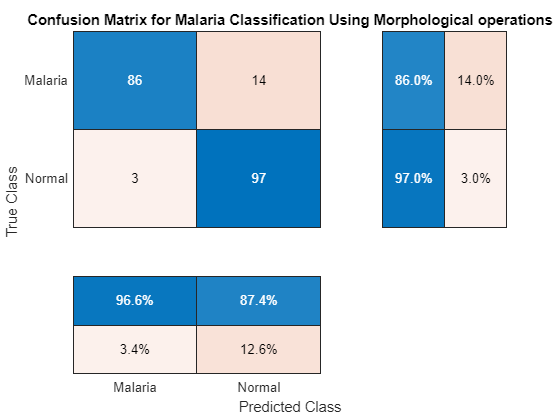

figure("Name",'Confusion Matrix')
cm = confusionchart(labelsC,predsC,'RowSummary','row-normalized','ColumnSummary','column-normalized');
cm.Title = 'Confusion Matrix for Malaria Classification Using Morphological operations';

%saveas(gcf,'confusion_mat.png')

### Performance Metrics

[accuracy, sensitivity, specificity, precision, recall, f_measure, gmean] = get_metrics(labels,preds);
fprintf('Accuracy  : %.2f', accuracy*100);

Accuracy  : 91.50

fprintf('Sensitivity : %.3f', sensitivity);

Sensitivity : 0.860

fprintf('Specificity : %.3f', specificity);

Specificity : 0.970

fprintf('Precision : %.3f', precision);

Precision : 0.966

fprintf('Recall : %.3f', recall);

Recall : 0.860

fprintf('F1-Score: %.3f', f_measure );

F1-Score: 0.910